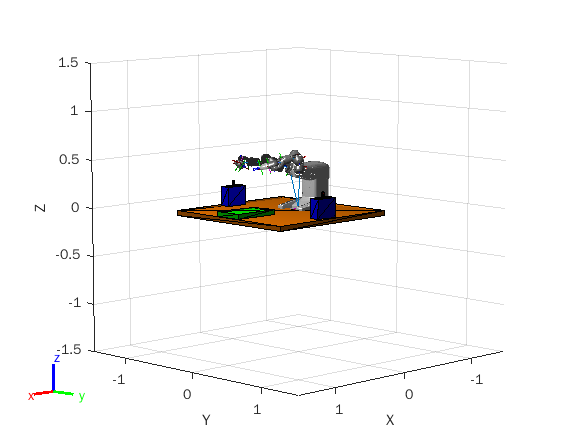

robot = loadrobot('abbYumi', 'Gravity', [0 0 -9.81]);
iviz = interactiveRigidBodyTree(robot);
ax = gca;
plane = collisionBox(1.5,1.5,0.05);
plane.Pose = trvec2tform([0.25 0 -0.025]);
show(plane,'Parent', ax);

leftShelf = collisionBox(0.25,0.1,0.2);
leftShelf.Pose = trvec2tform([0.3 -.65 0.1]);
[~, patchObj] = show(leftShelf,'Parent',ax);
patchObj.FaceColor = [0 0 1];

rightShelf = collisionBox(0.25,0.1,0.2);
rightShelf.Pose = trvec2tform([0.3 .65 0.1]);
[~, patchObj] = show(rightShelf,'Parent',ax);
patchObj.FaceColor = [0 0 1];

leftWidget = collisionCylinder(0.01, 0.07);
leftWidget.Pose = trvec2tform([0.3 -0.65 0.225]);
[~, patchObj] = show(leftWidget,'Parent',ax);
patchObj.FaceColor = [1 0 0];

rightWidget = collisionBox(0.03, 0.02, 0.07);
rightWidget.Pose = trvec2tform([0.3 0.65 0.225]);
[~, patchObj] = show(rightWidget,'Parent',ax);
patchObj.FaceColor = [1 0 0];

centerTable = collisionBox(0.5,0.3,0.05);
centerTable.Pose = trvec2tform([0.75 0 0.025]);
[~, patchObj] = show(centerTable,'Parent',ax);
patchObj.FaceColor = [0 1 0];
iviz.MarkerBodyName = "gripper_r_base";
iviz.MarkerBodyName = "yumi_link_2_r";
iviz.MarkerControlMethod = "JointControl";
addConfiguration(iviz)
load abbYumiSaveTrajectoryWaypts.mat

removeConfigurations(iviz) % Clear stored configurations

% Start at a valid starting configuration
iviz.Configuration = startingConfig;
addConfiguration(iviz)

% Specify the entire set of waypoints
iviz.StoredConfigurations = [startingConfig, ...
                             graspApproachConfig, ...
                             graspPoseConfig, ...
                             graspDepartConfig, ...
                             placeApproachConfig, ...
                             placeConfig, ...
                             placeDepartConfig, ...
                             startingConfig];
numSamples = 100*size(iviz.StoredConfigurations, 2) + 1;
[q,~,~, tvec] = trapveltraj(iviz.StoredConfigurations,numSamples,'EndTime',2);
iviz.ShowMarker = false;
showFigure(iviz)
rateCtrlObj = rateControl(numSamples/(max(tvec) + tvec(2)));
for i = 1:numSamples
    iviz.Configuration = q(:,i);
    waitfor(rateCtrlObj);
end